clear; close; clc;
% Inictial condition
x_0 = 0;
z_0 = 0;
t_0 = 0;

% Boundary values
%x_f = %range
z_f = 0;

%CARTRIDGE, 105-MILLIMETER: HERA, M913
Nozzle_Exit_Diameter = 0.05; %m
Hydrolic_Diameter = 0.105; %m
Projectile_Length = 0.557; %m
Nose_Length = 0.408; %m

Nozzle_Exit_Area = pi * (Nozzle_Exit_Diameter/2)^2;

Projectile_Mass = 17.5 % I have selected this

Projectile_Mass = 17.5000


%launch conditions
%z_0 = -3660; %m
V_muzzle = 625; %m/s


Gun_Elevation = deg2rad(45);
lString = "";

for Gun_Elevation = deg2rad(40:2:80)

%xi = atan2(-v_z, v_x); % calculate flight path angle
v_x_0 = V_muzzle * cos(Gun_Elevation);
v_z_0 = V_muzzle * sin(-Gun_Elevation);

V = [v_x_0, v_z_0];
X = [x_0, z_0];
m = Projectile_Mass;

% parameters need for simulation
state = [V,X,m]
tspan = [0 120]

% simulate the flight
[rawT,rawStates] = ode45(@(t,y) dynamics(t,y,Projectile_Length,Nose_Length,Hydrolic_Diameter, Nozzle_Exit_Area,true), tspan, state);

% remove states after the bullet has hit the ground (these dont exist)
flyingStates = rawStates(:,4) <= 0;
states = rawStates(flyingStates,:);
t = rawT(flyingStates);

V = states(:,1:2);
X = states(:,3:4);
m = states(:,5);

plot(X(:,1),-X(:,2));
lString = [lString; "elev: "+Gun_Elevation];
hold on;
%plot(X(:,1),[V(:,1),-V(:,2)])
end

state =   478.7778 -401.7423         0         0   17.5000


tspan =      0   120


state =   464.4655 -418.2066         0         0   17.5000


tspan =      0   120


state =   449.5874 -434.1615         0         0   17.5000


tspan =      0   120


state =   434.1615 -449.5874         0         0   17.5000


tspan =      0   120


state =   418.2066 -464.4655         0         0   17.5000


tspan =      0   120


state =   401.7423 -478.7778         0         0   17.5000


tspan =      0   120


state =   384.7884 -492.5067         0         0   17.5000


tspan =      0   120


state =   367.3658 -505.6356         0         0   17.5000


tspan =      0   120


state =   349.4956 -518.1485         0         0   17.5000


tspan =      0   120


state =   331.1995 -530.0301         0         0   17.5000


tspan =      0   120


state =   312.5000 -541.2659         0         0   17.5000


tspan =      0   120


state =   293.4197 -551.8422         0         0   17.5000


tspan =      0   120


state =   273.9820 -561.7463         0         0   17.5000


tspan =      0   120


state =   254.2104 -570.9659         0         0   17.5000


tspan =      0   120


state =   234.1291 -579.4899         0         0   17.5000


tspan =      0   120


state =   213.7626 -587.3079         0         0   17.5000


tspan =      0   120


state =   193.1356 -594.4103         0         0   17.5000


tspan =      0   120


state =   172.2733 -600.7886         0         0   17.5000


tspan =      0   120


state =   151.2012 -606.4348         0         0   17.5000


tspan =      0   120


state =   129.9448 -611.3423         0         0   17.5000


tspan =      0   120


state =   108.5301 -615.5048         0         0   17.5000


tspan =      0   120


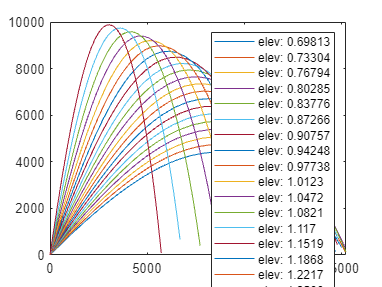


lString = lString(2:end);
legend(lString);

function dydt = dynamics(t,y,l,l_N,d, A_e, isCoasting)
    V = y(1:2);
    X = y(3:4);
    m = y(5);
    
    % compute forces
    F_drag = -V/norm(V) * drag_body(-X(2), norm(V), l, l_N, d, A_e, true); % balistic trajectory -> pointing in direction of velociy
    F_g = [0;1] * 6.6743E-11 * (5.9722E24)*m / (6371E3 - X(2))^2; % gravity = G * m_e * m_missile / (r_e+alt)^2
    F_propulsion = 0;

    % net force
    F_net = F_drag + F_propulsion + F_g;

    % compute mass
    mdot = 0; % not thrust modeling yet

    % equation of motion
    Vdot = (F_net - V * mdot) / m;

    % position
    Xdot = V;

    dydt = [Vdot;Xdot;mdot];

end
